% 3.1 From the course website download D_mpg.mat
load ('D_mpg.mat')

% 3.2 Prepare matrix X_tr and y_tr based on Eq. (E1.2).
y = D_mpg(7,:)';
M = length(y);
P = 314;
T = M - P;
X = D_mpg(1:6,:);
Xh = [X; ones(1,M)];
Xh_tr = Xh(:,1:P);
y_tr = y(1:P);

% 3.3 Prepare test data X_te and associated output y_te . 
Xh_te = Xh(:,P+1:M);
y_te = y(P+1:M); 

% 3.4 Prepare MATLAB code to compute optimal parameter w^* for the model in
% (E1.1) using Eq (E1.3)
w = pinv(Xh_tr')*y_tr;

% 3.5 Apply the optimized model to the train and test data respectively, and evaluate the root-mean-squared error
rmse_train = RMSE(w, Xh_tr, y_tr,314)

rmse_train = 3.5668

rmse_test = RMSE(w, Xh_te, y_te,78)

rmse_test = 2.6662

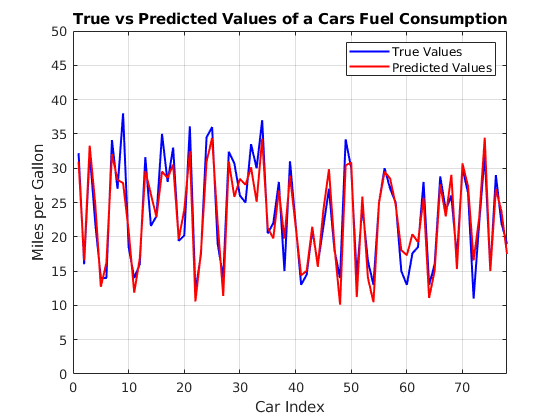



% 3.6 For comparison, in a single figure, plot the "ground truth” output y_te as a curve colored in blue and its prediction
% as the second curve colored in red. 
w_padded_y_te = repmat(w,1,78);
y_te_prediction = dot(w_padded, Xh_te, 1); 

set(gca, 'fontsize', 14)
ind = [1:78];
plot(ind, y_te, 'b-', ind, y_te_prediction, 'r-', 'LineWidth', 1.5)
grid on; 
axis([0 78 0 50])
xlabel('Car Index')
ylabel('Miles per Gallon')
title('True vs Predicted Values of a Cars Fuel Consumption')
legend('True Values', 'Predicted Values')


% Bonus Task 
rho = 0.1; 
gamma = 0.5; 
epsilon = 0.01; 
w_0 = [0.8239 0.7633 0.8131 0.6941 0.4657 0.9926 0.8673]';

w_0 =     0.8239
    0.7633
    0.8131
    0.6941
    0.4657
    0.9926
    0.8673


function r = RMSE(w,x,y,n)
% w is the vector that includes the optimal weight and bias, x is a
% collection of data points (with parameters) for which we want to predict
% something, y is a collection of the true prediction values, n is the
% number of samples in the dataset 

    w_padded = repmat(w,1,n); % number of columns corresponds to the number of testing samples 
    wTx = dot(w_padded, x, 1); % returns a vector where each entry is the dot product of a testing sample and w
    
    sum_input = (wTx'-y).^2; % subtracting the true value of y from the estimated value of y and squaring each term
    norm_sum = sum(sum_input)/n; % sum of each term in sum_input, divided by the total number of terms 
    
    r = sqrt(norm_sum); % Root mean squared error 
end